% ========================================================
% === SCRIPT COMPLETO: PIPELINE SVD_BC + GCN SU VOLTI   ===
% ========================================================
clear; clc; close all;
rng(0);

%% ----------------------------------------------------------------
%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------
projectRoot = '/Users/giuseppebonomo/Desktop/UNIPA CdLM Ing_Informatica/1 anno 2023-2024/1 Semestre 2023-2024/Metodi Numerici Avanzati/ProgettoMetodi';
addpath(genpath(projectRoot));              % tutte le subfolder

this_folder  = pwd;
results_path = fullfile(this_folder, 'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% ----------------------------------------------------------------
%% 1) PARAMETRI GLOBALI SVD_BC
%% ----------------------------------------------------------------
tol   = 1e-4;
maxit = 1000;
energy_threshold = 0.95;   % mantieni il 95% dell’energia

%% ----------------------------------------------------------------
%% 2) CARICAMENTO DATASET ORL & MEAN FACE
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset ORL...\n');   t = tic;

>>> Caricamento dataset ORL...


load('dataset/volti_dataset_Yale.mat');           % A (m×n), labels
A = double(A) / 255;
labels = labels(:);
fprintf('   fatto in %.2f s\n', toc(t));

   fatto in 0.04 s



[m, n] = size(A);
img_h = 112;  img_w = 92;
num_classes = max(labels);

fprintf('>>> Calcolo volto medio...\n');      t = tic;

>>> Calcolo volto medio...


mean_face = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
fprintf('   ok in %.2f s\n', toc(t));

   ok in 0.00 s



fprintf('>>> Centratura dati...\n');           t = tic;

>>> Centratura dati...


A_centered = A - mean_face;
fprintf('   ok in %.2f s\n', toc(t));

   ok in 0.00 s



%% ----------------------------------------------------------------
%% 3) SVD_BC su dati centrati
%% ----------------------------------------------------------------
fprintf('>>> Lancio svd_BC (tol=%.1e,maxit=%d)...\n', tol, maxit);

>>> Lancio svd_BC (tol=1.0e-04,maxit=1000)...


t = tic;
[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 165x165 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=165 ... 

iter=1001 time=1.90 s
         [qr_eig] deflazione k=164 ... 

iter=1001 time=1.78 s
         [qr_eig] deflazione k=163 ... 

iter=1001 time=1.34 s
         [qr_eig] deflazione k=162 ... iter=338 time=0.51 s
         [qr_eig] deflazione k=161 ... 

iter=1001 time=1.50 s
         [qr_eig] deflazione k=160 ... iter=309 time=0.51 s
         [qr_eig] deflazione k=159 ... 

iter=1001 time=1.40 s
         [qr_eig] deflazione k=158 ... 

iter=1001 time=1.32 s
         [qr_eig] deflazione k=157 ... 

iter=1001 time=1.31 s
         [qr_eig] deflazione k=156 ... iter=765 time=1.01 s
         [qr_eig] deflazione k=155 ... 

iter=1001 time=1.20 s
         [qr_eig] deflazione k=154 ... 

iter=1001 time=1.23 s
         [qr_eig] deflazione k=153 ... 

iter=1001 time=1.20 s
         [qr_eig] deflazione k=152 ... 

iter=1001 time=1.15 s
         [qr_eig] deflazione k=151 ... 

iter=1001 time=1.18 s
         [qr_eig] deflazione k=150 ... 

iter=1001 time=1.18 s
         [qr_eig] deflazione k=149 ... 

iter=1001 time=1.12 s
         [qr_eig] deflazione k=148 ... 

iter=1001 time=1.15 s
         [qr_eig] deflazione k=147 ... 

iter=1001 time=1.45 s
         [qr_eig] deflazione k=146 ... 

iter=1001 time=1.09 s
         [qr_eig] deflazione k=145 ... 

iter=1001 time=1.15 s
         [qr_eig] deflazione k=144 ... 

iter=1001 time=1.16 s
         [qr_eig] deflazione k=143 ... 

iter=1001 time=1.27 s
         [qr_eig] deflazione k=142 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=141 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=140 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=139 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=138 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=137 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=136 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=135 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=134 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=133 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=132 ... 

iter=1001 time=0.69 s
         [qr_eig] deflazione k=131 ... 

iter=1001 time=0.69 s
         [qr_eig] deflazione k=130 ... 

iter=1001 time=0.67 s
         [qr_eig] deflazione k=129 ... 

iter=1001 time=0.66 s
         [qr_eig] deflazione k=128 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=127 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=126 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=125 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=124 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=123 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=122 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=121 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=120 ... iter=90 time=0.05 s
         [qr_eig] deflazione k=119 ... 

iter=1001 time=0.58 s
         [qr_eig] deflazione k=118 ... 

iter=1001 time=0.56 s
         [qr_eig] deflazione k=117 ... 

iter=1001 time=0.56 s
         [qr_eig] deflazione k=116 ... 

iter=1001 time=0.54 s
         [qr_eig] deflazione k=115 ... 

iter=1001 time=0.54 s
         [qr_eig] deflazione k=114 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=113 ... iter=514 time=0.27 s
         [qr_eig] deflazione k=112 ... 

iter=1001 time=0.50 s
         [qr_eig] deflazione k=111 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=110 ... 

iter=1001 time=0.50 s
         [qr_eig] deflazione k=109 ... 

iter=1001 time=0.49 s
         [qr_eig] deflazione k=108 ... 

iter=1001 time=0.48 s
         [qr_eig] deflazione k=107 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=106 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=105 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=104 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=103 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=102 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=101 ... iter=989 time=0.43 s
         [qr_eig] deflazione k=100 ... 

iter=1001 time=0.42 s
         [qr_eig] deflazione k=99 ... 

iter=1001 time=0.42 s
         [qr_eig] deflazione k=98 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=97 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=96 ... 

iter=1001 time=0.41 s
         [qr_eig] deflazione k=95 ... 

iter=1001 time=0.40 s
         [qr_eig] deflazione k=94 ... 

iter=1001 time=0.38 s
         [qr_eig] deflazione k=93 ... 

iter=1001 time=0.38 s
         [qr_eig] deflazione k=92 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=91 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=90 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=89 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=88 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=87 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=86 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=85 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=84 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=83 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=82 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=81 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=80 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=79 ... 

iter=1001 time=0.29 s
         [qr_eig] deflazione k=78 ... 

iter=1001 time=0.28 s
         [qr_eig] deflazione k=77 ... iter=344 time=0.10 s
         [qr_eig] deflazione k=76 ... 

iter=1001 time=0.27 s
         [qr_eig] deflazione k=75 ... 

iter=1001 time=0.27 s
         [qr_eig] deflazione k=74 ... 

iter=1001 time=0.26 s
         [qr_eig] deflazione k=73 ... 

iter=1001 time=0.25 s
         [qr_eig] deflazione k=72 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=71 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=70 ... iter=906 time=0.21 s
         [qr_eig] deflazione k=69 ... 

iter=1001 time=0.23 s
         [qr_eig] deflazione k=68 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=67 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=66 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=65 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=64 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=63 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=62 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=61 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=60 ... 

iter=1001 time=0.19 s
         [qr_eig] deflazione k=59 ... 

iter=1001 time=0.19 s
         [qr_eig] deflazione k=58 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=57 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=56 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=55 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=54 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=53 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=52 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=51 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=48 ... 

iter=1001 time=0.14 s
         [qr_eig] deflazione k=47 ... 

iter=1001 time=0.13 s
         [qr_eig] deflazione k=46 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=45 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=41 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=40 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         

fprintf('   completata in %.2f s\n', toc(t));

   completata in 41.69 s


save(fullfile(results_path,'svd_data.mat'),'U','S','V');

%% ----------------------------------------------------------------
%% 4) Selezione di k da energia cumulata
%% ----------------------------------------------------------------
eigvals = diag(S);
energy  = cumsum(eigvals) / sum(eigvals);
k = find(energy > energy_threshold, 1);
fprintf('>>> Uso k = %d componenti (%.1f%% energia)\n', k, 100*energy(k));

>>> Uso k = 161 componenti (95.4% energia)



%% ----------------------------------------------------------------
%% 5) Calcolo proiezioni PCA [n_samples×k]
%% ----------------------------------------------------------------
U_k         = U(:,1:k);
projections = (U_k' * A_centered)';   % [n×k]

%% ----------------------------------------------------------------
%% 6) Visualizzazione mean & prime eigenfaces
%% ----------------------------------------------------------------
fprintf('>>> Visualizzazione SVD results...\n');

>>> Visualizzazione SVD results...


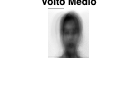


figure('Name','Volto Medio','NumberTitle','off');
imshow(reshape(mean_face,img_h,img_w),[]);
title('Volto Medio');
saveas(gcf, fullfile(results_path,'volto_medio.png'));

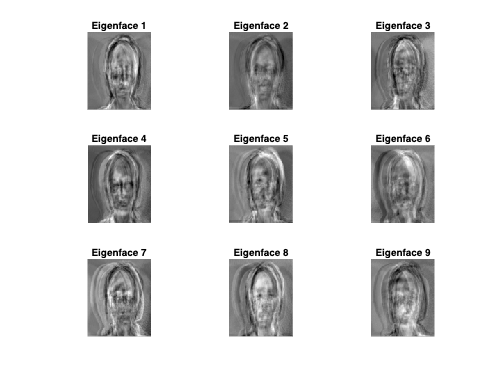


figure('Name','Eigenfaces','NumberTitle','off');
for i = 1:9
    subplot(3,3,i);
    imshow(reshape(U(:,i),img_h,img_w),[]);
    title(sprintf('Eigenface %d',i));
end
saveas(gcf, fullfile(results_path,'eigenfaces.png'));


%% ----------------------------------------------------------------
%% 7) PREPARAZIONE FEATURE E ONE‐HOT
%% ----------------------------------------------------------------
X = projections;                      % [n_samples×k]
num_samples = size(X,1);
Y = zeros(num_classes, num_samples);
for i = 1:num_samples
    Y(labels(i), i) = 1;
end

%% ----------------------------------------------------------------
%% 8) COSTRUZIONE DEL GRAFO DI SIMILARITÀ
%% ----------------------------------------------------------------
K = 10;   % numero di vicini per nodo
A_graph = zeros(num_samples);
for i = 1:num_samples
    dists = sum((X - X(i,:)).^2, 2);
    [~, idx] = sort(dists);
    nbrs = idx(2:K+1);
    A_graph(i, nbrs) = 1;
end
A_graph = max(A_graph, A_graph');     % simmetrico
A_hat   = A_graph + eye(num_samples);

D       = diag(sum(A_hat,2));
A_hat_norm = D^(-0.5) * A_hat * D^(-0.5);

%% ----------------------------------------------------------------
%% 9) SPLIT TRAIN/TEST
%% ----------------------------------------------------------------
rng(0);
perm  = randperm(num_samples);
split = round(0.8 * num_samples);
train_idx = perm(1:split);
test_idx  = perm(split+1:end);

X_train = X(train_idx,:);
Y_train = Y(:,train_idx);
X_test  = X(test_idx,:);
Y_test  = Y(:,test_idx);

A_train = A_hat_norm(train_idx,train_idx);
A_test  = A_hat_norm(test_idx, train_idx);

%% ----------------------------------------------------------------
%% 10) TRAINING GCN
%% ----------------------------------------------------------------
epochs        = 100;
learning_rate = 0.01;
fprintf('>>> Training GCN...\n');

>>> Training GCN...


[W, loss_hist] = gcn_train(X_train, Y_train, A_train, epochs, learning_rate);

[GCN] Epoch  10/100 - Loss: 2.7001
[GCN] Epoch  20/100 - Loss: 2.6999
[GCN] Epoch  30/100 - Loss: 2.6997
[GCN] Epoch  40/100 - Loss: 2.6995
[GCN] Epoch  50/100 - Loss: 2.6993
[GCN] Epoch  60/100 - Loss: 2.6991
[GCN] Epoch  70/100 - Loss: 2.6989
[GCN] Epoch  80/100 - Loss: 2.6986
[GCN] Epoch  90/100 - Loss: 2.6984
[GCN] Epoch 100/100 - Loss: 2.6982



%% ----------------------------------------------------------------
%% 11) VALUTAZIONE SU TEST SET
%% ----------------------------------------------------------------
Z_test = (A_test * X_train) * W;  % [n_test×num_classes]
Z_test = Z_test';
Z_test = Z_test - max(Z_test,[],1);
expZ   = exp(Z_test);
A2     = expZ ./ sum(expZ,1);
[~, y_pred] = max(A2,[],1);
[~, y_true] = max(Y(:,test_idx),[],1);

acc = mean(y_pred' == y_true');
fprintf('>>> Test accuracy (GCN): %.2f%%\n', acc*100);

>>> Test accuracy (GCN): 12.12%


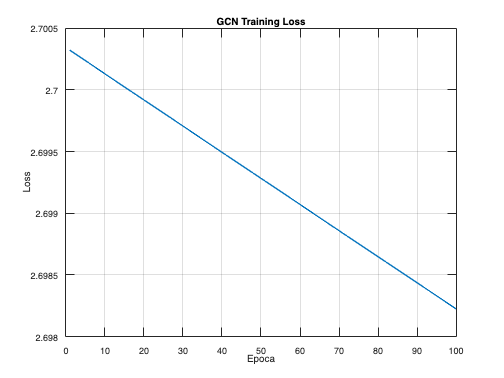


%% ----------------------------------------------------------------
%% 12) VISUALIZZAZIONE LOSS
%% ----------------------------------------------------------------
figure;
plot(1:epochs, loss_hist, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Loss');
title('GCN Training Loss');
grid on;
saveas(gcf, fullfile(results_path,'gcn_loss.png'));


fprintf('>>> Fine script (totale %.2f s)\n', toc);

>>> Fine script (totale 110.32 s)
